**1. Color balance , Saturation,and Demosaicing **

**(1)White balance**

Apply the white balance on "sky.jpg" and name the output image as "WhiteBalanceImage".


$$I(x,y)=0.299f_R(x,y)+0.587f_G(x,y)+0.114 f_B(x,y)\\
k_R=\frac{\overline I}{\overline{f_R}},k_G=\frac{\overline I}{\overline{f_G}},k_B=\frac{\overline I}{\overline{f_B}}\\$$


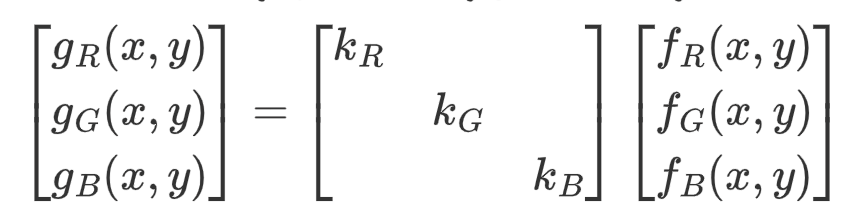

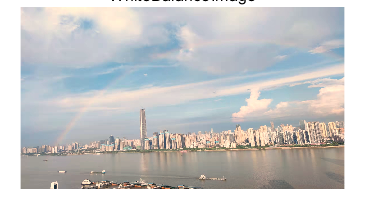

clear;clf;
RGB = im2double(imread("sky.jpg"));
R = RGB(:,:,1);
G = RGB(:,:,2);
B = RGB(:,:,3);
I = 0.299*R + 0.587*G + 0.114*B;
kr = mean(I(:))/mean(R(:));
kg = mean(I(:))/mean(G(:));
kb = mean(I(:))/mean(B(:));
WhiteBalanceImage = cat(3,kr*R,kg*G,kb*B);
figure;
imshow(WhiteBalanceImage);
title("WhiteBalanceImage");

**(2)Adjust Saturation**

Increase the saturation of  "sky.jpg" by 50% ,and name the output image as "SaturationImage".

**Also,You cannot use  the function“rgb2hsv()or hsv2rgb()”**


$$I=\frac{1}{3}(R+G+B)\\S=1-\frac{3min(R,G,B)}{R+G+B}\\H=\begin{cases}\theta.G\geq B\\2\pi-\theta,G<B\end{cases}\\\theta=cos^{-1}[\frac{\frac12[(R-G)+(R-B)]}{\sqrt{(R-G)^2+(R-B)(G-B)}}]$$


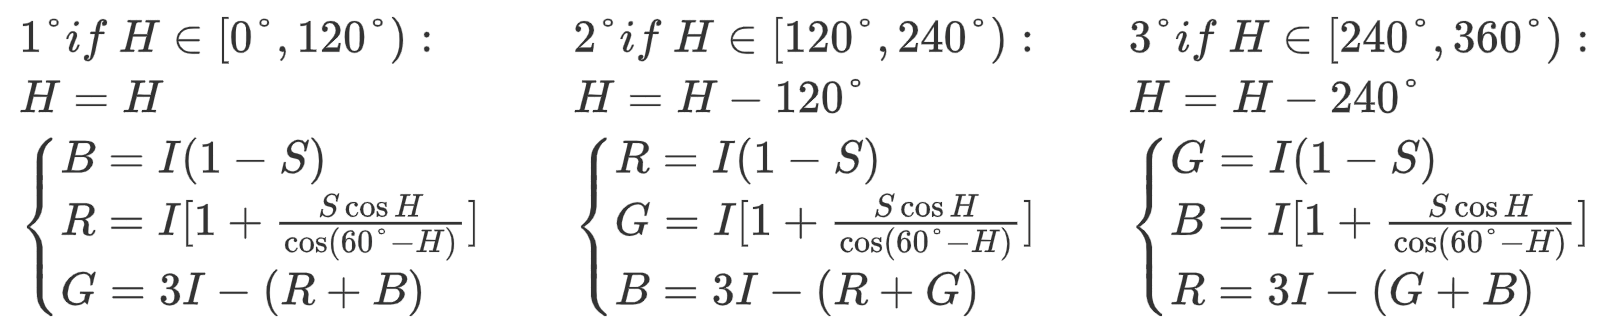

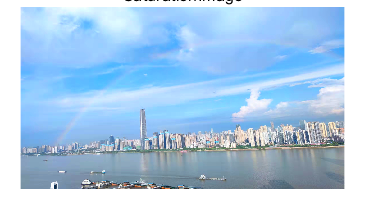

clear;clf;
RGB = im2double(imread("sky.jpg"));
R = RGB(:,:,1);
G = RGB(:,:,2);
B = RGB(:,:,3);
[r,c] = size(R);

for i = 1:r
    for j = 1:c
        I = (R(i,j) + G(i,j) + B(i,j))/3;
        S = (1 - 3*min([R(i,j),G(i,j),B(i,j)])/(R(i,j) + G(i,j) + B(i,j)))*1.5;
        theta = acos(((R(i,j) - G(i,j))+(R(i,j) - B(i,j))) * 0.5 / sqrt((R(i,j) - G(i,j))^2 + (R(i,j) - B(i,j))*(G(i,j) - B(i,j))));

        if G(i,j) >= B(i,j)
            H = theta;
        elseif G(i,j) < B(i,j)
            H = 2*pi - theta;
        end
        
        if (H >= 0) && (H < pi*2/3)
            B(i,j) = I*(1 - S);
            R(i,j) = I*(1 + S*cos(H)/cos(pi/3 - H));
            G(i,j) = 3*I - (R(i,j) + B(i,j));
        elseif (H >= pi*2/3) && (H < pi*4/3)
            H = H - pi*2/3;
            R(i,j) = I*(1 - S);
            G(i,j) = I*(1 + S*cos(H)/cos(pi/3 - H));
            B(i,j) = 3*I - (R(i,j) + G(i,j));
        elseif (H >= pi*4/3) && (H < pi*2)
            H = H - pi*4/3;
            G(i,j) = I*(1 - S);
            B(i,j) = I*(1 + S*cos(H)/cos(pi/3 - H));
            R(i,j) = 3*I - (B(i,j) + G(i,j));
        end
    end
end

SaturationImage = cat(3,R,G,B);
figure;
imshow(SaturationImage);
title("SaturationImage");

**(3)Demosaicing**

The initial image is given as "flower.mat". Please use the demosaicing algorithm to convert this single-channel image to a three-channel RGB image. Name the output image as "RGBImage". **You cannot use the function“demosaic()”**

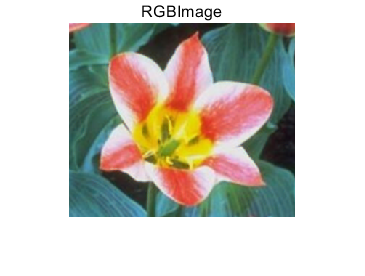

clear;clf;
load("flower.mat");
flower = im2double(flower);
[r,c] = size(flower);
R = zeros(r,c);G = zeros(r,c);B = zeros(r,c);

R(1,1) = flower(2,2);R(r,c) = flower(r-1,c-1);
R(1,c) = flower(2,c-1);R(r,1) = flower(r-1,2);
G(1,1) = (flower(2,1)+flower(1,2))/2;G(r,c) = (flower(r,c-1)+flower(r-1,c))/2;
G(1,c) = (flower(2,c)+flower(1,c-1))/2;G(r,1) = (flower(r-1,1)+flower(r,2))/2;
B(1,1) = flower(1,1);B(r,c) = flower(r,c);
B(1,c) = flower(1,c);B(r,1) = flower(r,1);

for i = 2:(r-1)
    if mod(i,2) == 0
        R(i,1) = flower(i,2);
        R(i,c) = flower(i,c-1);
        G(i,1) = flower(i,1);
        G(i,c) = flower(i,c);
        B(i,1) = (flower(i-1,1)+flower(i+1,1))/2;
        B(i,c) = (flower(i-1,c)+flower(i+1,c))/2;
    elseif mod(i,2) ~= 0
        R(i,1) = (flower(i-1,2)+flower(i+1,2))/2;
        R(i,c) = (flower(i-1,c-1)+flower(i+1,c-1))/2;
        G(i,1) = (flower(i-1,1)+flower(i+1,1))/2;
        G(i,c) = (flower(i-1,c)+flower(i+1,c))/2;
        B(i,1) = flower(i,1);
        B(i,c) = flower(i,c);
    end
end

for j = 2:(c-1)
    if mod(j,2) == 0
        R(1,j) = flower(2,j);
        R(r,j) = flower(r-1,j);
        G(1,j) = flower(1,j);
        G(r,j) = flower(r,j);
        B(1,j) = (flower(1,j-1)+flower(1,j+1))/2;
        B(r,j) = (flower(r,j-1)+flower(r,j+1))/2;
    elseif mod(j,2) ~= 0
        R(1,j) = (flower(2,j-1)+flower(2,j+1))/2;
        R(r,j) = (flower(r-1,j-1)+flower(r-1,j+1))/2;
        G(1,j) = (flower(1,j-1)+flower(1,j+1))/2;
        G(r,j) = (flower(r,j-1)+flower(r,j+1))/2;
        B(1,j) = flower(1,j);
        B(r,j) = flower(r,j);
    end
end

for i = 2:(r-1)
    for j = 2:(c-1)
        if (mod(i,2) == 0) && (mod(j,2) == 0)
            R(i,j) = flower(i,j);            
            G(i,j) = (flower(i-1,j)+flower(i+1,j)+flower(i,j-1)+flower(i,j+1))/4;
            B(i,j) = (flower(i-1,j-1)+flower(i-1,j+1)+flower(i+1,j-1)+flower(i+1,j+1))/4;
        elseif (mod(i,2) == 0) && (mod(j,2) ~= 0)
            R(i,j) = (flower(i,j-1)+flower(i,j+1))/2;
            G(i,j) = flower(i,j);            
            B(i,j) = (flower(i-1,j)+flower(i+1,j))/2;
        elseif (mod(i,2) ~= 0) && (mod(j,2) == 0)
            R(i,j) = (flower(i-1,j)+flower(i+1,j))/2;            
            G(i,j) = flower(i,j);
            B(i,j) = (flower(i,j-1)+flower(i,j+1))/2;
        elseif (mod(i,2) ~= 0) && (mod(j,2) ~= 0)
            R(i,j) = (flower(i-1,j-1)+flower(i-1,j+1)+flower(i+1,j-1)+flower(i+1,j+1))/4;            
            G(i,j) = (flower(i-1,j)+flower(i+1,j)+flower(i,j-1)+flower(i,j+1))/4;
            B(i,j) = flower(i,j);
        end
    end
end

RGBImage = cat(3,R,G,B);
figure;
imshow(RGBImage);
title("RGBImage");

## 2. Noise generation and degeneration

(1) ***Noise generation***

Add the following noise to the initial image separately：

Gaussian noise：mean and variance are 25 and 25 respectively;

Salt-and-pepper noise：intensities are 0 and 255 with probabilities $P_{salt} = P_{pepper} = 0.05$;

Name the output images as "NoiseImage1", "NoiseImage2" and display both images. **You are free to use the function "imnoise" or other built-in functions to generate the noise.**

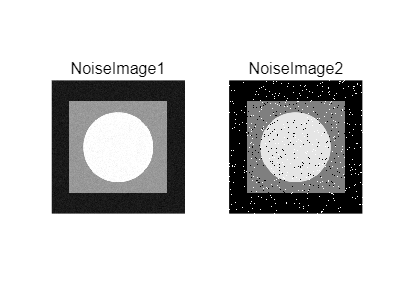

clear;clf;
load("init_img.mat");
NoiseImage1 = imnoise(init_img,"gaussian",25/255,25/255^2);
NoiseImage2 = imnoise(init_img,"salt & pepper",0.05);
subplot(1,2,1);imshow(NoiseImage1);
title("NoiseImage1");
subplot(1,2,2);imshow(NoiseImage2);
title("NoiseImage2");

**(2) *****Noise degeneration***

Please design a median filter and an average filter, and apply both your filters to the "NoiseImage1" and"NoiseImage2". Then display all your output image results.

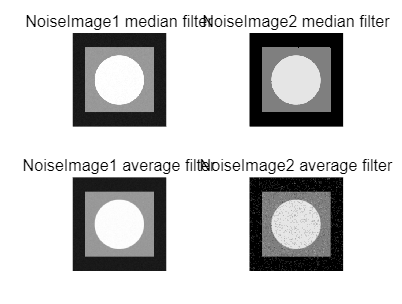

clf;
subplot(2,2,1);imshow(medfilt2(NoiseImage1));
title("NoiseImage1 median filter");
subplot(2,2,2);imshow(medfilt2(NoiseImage2));
title("NoiseImage2 median filter");
h = ones(3,3)/9;
subplot(2,2,3);imshow(imfilter(NoiseImage1,h));
title("NoiseImage1 average filter");
subplot(2,2,4);imshow(imfilter(NoiseImage2,h));
title("NoiseImage2 average filter");

## 3. **Log/gamma Transformation and histogram equalization and matching**

(1)***Histogram***

Develop a function which computes the **gray-level histogram** of the "origin.tif". Then using this function to find the histogram and display it.

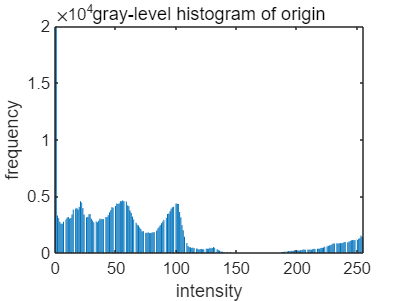

clear;clf;
origin = imread("origin.png");
figure;
bar(imhist0(origin));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("gray-level histogram of origin");
xlabel("intensity");
ylabel("frequency");

**(2)Log Transformation and Gamma Transformation**

use transform function $s=c\log(1+r)$  and $s=c\cdot r^\gamma$ to deal with the image.Display the output image and its gray-level histogram.

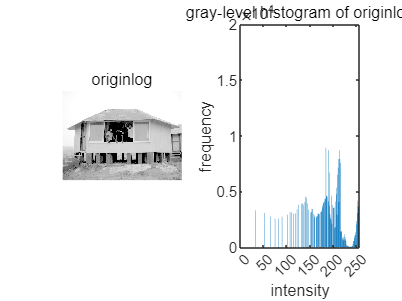

clear;clf;
origin = imread("origin.png");
originlog = im2uint8(mat2gray(log(1+double(origin)))); %c=1
subplot(1,2,1);
imshow(originlog);
title("originlog");
subplot(1,2,2);
bar(imhist0(originlog));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("gray-level histogram of originlog");
xlabel("intensity");
ylabel("frequency");

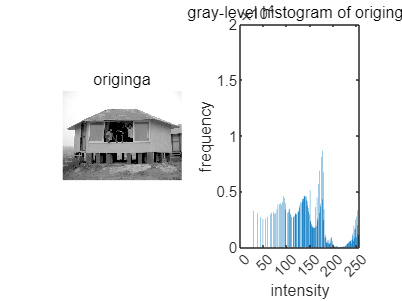


clf;
originga = im2uint8(mat2gray(double(origin).^0.4)); %c=1
subplot(1,2,1);
imshow(originga);
title("originga");
subplot(1,2,2);
bar(imhist0(originga));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("gray-level histogram of originga");
xlabel("intensity");
ylabel("frequency");

**(3)*****Histogram equalization***

**Use the function histeq()** to apply histogram equalization on the "source.jpg". Then using this function to equalize the  histogram which you develop in 3.1. Display the output image and its gray-level histogram.

If you can design a function by youself instead of using function histeq() in this part, you can get a Bouns scores(5’)

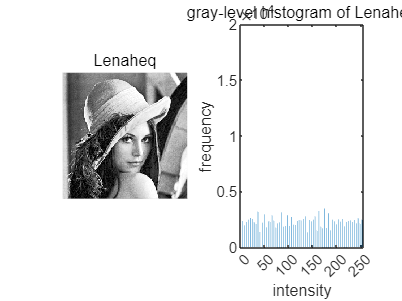

clear;clf;
origin = imread("origin.png");
originlog = im2uint8(mat2gray(log(1+double(origin))));
originga = im2uint8(mat2gray(double(origin).^0.4));
Lena = imread("Lena.png");
Lenaheq = histeq(Lena);

subplot(1,2,1);
imshow(Lenaheq);
title("Lenaheq");
subplot(1,2,2);
bar(imhist0(Lenaheq));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("gray-level histogram of Lenaheq");
xlabel("intensity");
ylabel("frequency");

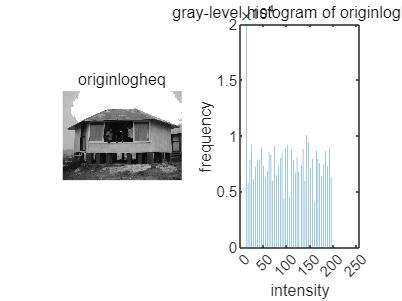


clf;
originlogheq = histeq(originlog);
subplot(1,2,1);
imshow(originlogheq);
title("originlogheq");
subplot(1,2,2);
bar(imhist0(originlogheq));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("gray-level histogram of originlogheq");
xlabel("intensity");
ylabel("frequency");

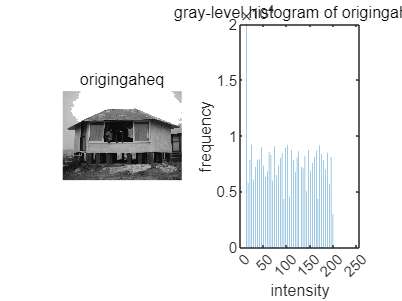


clf;
origingaheq = histeq(originga);
subplot(1,2,1);
imshow(origingaheq);
title("origingaheq");
subplot(1,2,2);
bar(imhist0(origingaheq));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("gray-level histogram of origingaheq");
xlabel("intensity");
ylabel("frequency");

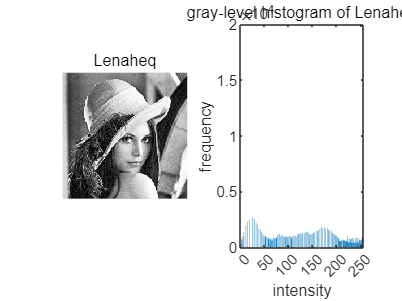




%self-design function part
clear;clf;
origin = imread("origin.png");
originlog = im2uint8(mat2gray(log(1+double(origin))));
originga = im2uint8(mat2gray(double(origin).^0.4));
Lena = imread("Lena.png");
Lenaheq = heq(Lena);

subplot(1,2,1);
imshow(Lenaheq);
title("Lenaheq");
subplot(1,2,2);
bar(imhist0(Lenaheq));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("gray-level histogram of Lenaheq");
xlabel("intensity");
ylabel("frequency");

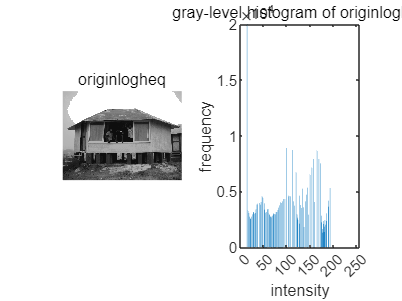


clf;
originlogheq = heq(originlog);
subplot(1,2,1);
imshow(originlogheq);
title("originlogheq");
subplot(1,2,2);
bar(imhist0(originlogheq));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("gray-level histogram of originlogheq");
xlabel("intensity");
ylabel("frequency");

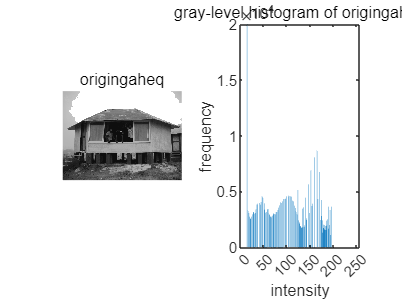


clf;
origingaheq = heq(originga);
subplot(1,2,1);
imshow(origingaheq);
title("origingaheq");
subplot(1,2,2);
bar(imhist0(origingaheq));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("gray-level histogram of origingaheq");
xlabel("intensity");
ylabel("frequency");

**(4)*****Histogram matching***

**Use the function histeq()**  to apply the histogram matching between the source image and the target image. Use this function to display the output image. And you also need to display the gray-level histogram of the source image, the target image and the output image.

If you can design a function by youself instead of using function histeq() in this part, you can get a Bouns scores(5’)

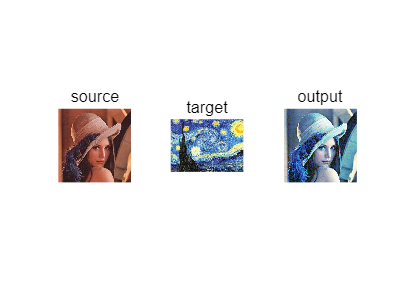

clear;clf;
Lena = imread("source.jpg");
target = imread("target.jpg");
output = cat(3,histeq(Lena(:,:,1),imhist0(target(:,:,1))),histeq(Lena(:,:,2),imhist0(target(:,:,2))),histeq(Lena(:,:,3),imhist0(target(:,:,3))));

subplot(1,3,1);imshow(Lena);title("source");
subplot(1,3,2);imshow(target);title("target");
subplot(1,3,3);imshow(output);title("output");

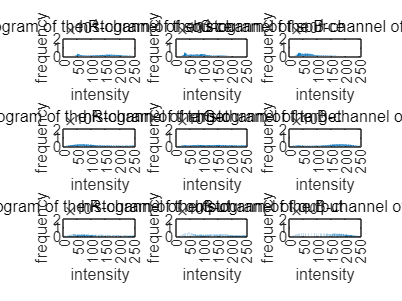


clf;
subplot(3,3,1);
bar(imhist0(Lena(:,:,1)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the R-channel of source");
xlabel("intensity");
ylabel("frequency");
subplot(3,3,2);
bar(imhist0(Lena(:,:,2)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the G-channel of source");
xlabel("intensity");
ylabel("frequency");
subplot(3,3,3);
bar(imhist0(Lena(:,:,3)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the B-channel of source");
xlabel("intensity");
ylabel("frequency");

subplot(3,3,4);
bar(imhist0(target(:,:,1)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the R-channel of target");
xlabel("intensity");
ylabel("frequency");
subplot(3,3,5);
bar(imhist0(target(:,:,2)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the G-channel of target");
xlabel("intensity");
ylabel("frequency");
subplot(3,3,6);
bar(imhist0(target(:,:,3)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the B-channel of target");
xlabel("intensity");
ylabel("frequency");

subplot(3,3,7);
bar(imhist0(output(:,:,1)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the R-channel of output");
xlabel("intensity");
ylabel("frequency");
subplot(3,3,8);
bar(imhist0(output(:,:,2)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the G-channel of output");
xlabel("intensity");
ylabel("frequency");
subplot(3,3,9);
bar(imhist0(output(:,:,3)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the B-channel of output");
xlabel("intensity");
ylabel("frequency");

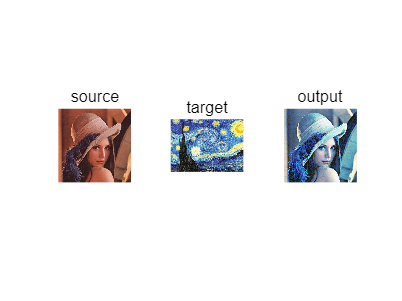




%self-design function part
clear;clf;
Lena = imread("source.jpg");
target = imread("target.jpg");
output = hismat(Lena,target);

subplot(1,3,1);imshow(Lena);title("source");
subplot(1,3,2);imshow(target);title("target");
subplot(1,3,3);imshow(output);title("output");

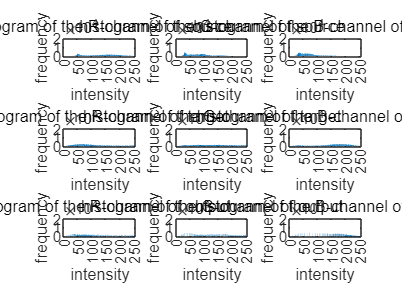


clf;
subplot(3,3,1);
bar(imhist0(Lena(:,:,1)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the R-channel of source");
xlabel("intensity");
ylabel("frequency");
subplot(3,3,2);
bar(imhist0(Lena(:,:,2)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the G-channel of source");
xlabel("intensity");
ylabel("frequency");
subplot(3,3,3);
bar(imhist0(Lena(:,:,3)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the B-channel of source");
xlabel("intensity");
ylabel("frequency");

subplot(3,3,4);
bar(imhist0(target(:,:,1)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the R-channel of target");
xlabel("intensity");
ylabel("frequency");
subplot(3,3,5);
bar(imhist0(target(:,:,2)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the G-channel of target");
xlabel("intensity");
ylabel("frequency");
subplot(3,3,6);
bar(imhist0(target(:,:,3)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the B-channel of target");
xlabel("intensity");
ylabel("frequency");

subplot(3,3,7);
bar(imhist0(output(:,:,1)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the R-channel of output");
xlabel("intensity");
ylabel("frequency");
subplot(3,3,8);
bar(imhist0(output(:,:,2)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the G-channel of output");
xlabel("intensity");
ylabel("frequency");
subplot(3,3,9);
bar(imhist0(output(:,:,3)));axis([0 255 0 20000]);set(gca,'xtick',0:50:255);
title("histogram of the B-channel of output");
xlabel("intensity");
ylabel("frequency");

function originheq = heq(origin)
    [r,c] = size(origin);
    P = imhist0(origin)./(r*c);
    cdf = zeros(1,256);
    cdf(1,1) = P(1,1);
    for i = 2:256
        cdf(1,i) = cdf(1,i-1)+P(1,i);
    end
    sk = zeros(1,256);
    for i = 1:256
        sk(i) = round(cdf(i)*255);
    end
    originheq = origin;
    for i = 1:r
        for j = 1:c
            originheq(i,j) = sk(1,origin(i,j)+1);
        end
    end
end


function output = hismat(source,target)
    source1=source(:,:,1);
    source2=source(:,:,2);
    source3=source(:,:,3);
    
    target1=target(:,:,1);
    target2=target(:,:,2);
    target3=target(:,:,3);
    
    
    [rs1,cs1] = size(source1);
    [rt1,ct1] = size(target1);
    P1 = imhist0(source1)./(rs1*cs1);
    Ptar1 = imhist0(target1)./(rt1*ct1);
    
    cdf1 = zeros(1,256);
    sum = 0;
    for i = 1:256
        sum = sum + P1(i);
        cdf1(i) = sum*255;
    end
    
    cdftar1 = zeros(1,256);
    sum = 0;
    for i = 1:256
        sum = sum + Ptar1(i);
        cdftar1(i) = sum*255;
    end
    
    
    [rs2,cs2] = size(source2);
    [rt2,ct2] = size(target2);
    P2  = imhist0(source2)./(rs2*cs2);
    Ptar2 = imhist0(target2)./(rt2*ct2);
    
    cdf2 = zeros(1,256);
    sum = 0;
    for i = 1:256
        sum = sum + P2(i);
        cdf2(i) = sum*255;
    end
    
    cdftar2 = zeros(1,256);
    sum = 0;
    for i = 1:256
        sum = sum + Ptar2(i);
        cdftar2(i) = sum*255;
    end
    

    [rs3,cs3] = size(source3);
    [rt3,ct3] = size(target3);
    P3  = imhist0(source3)./(rs3*cs3);
    Ptar3 = imhist0(target3)./(rt3*ct3);
    
    cdf3 = zeros(1,256);
    sum = 0;
    for i = 1:256
        sum = sum + P3(i);
        cdf3(i) = sum*255;
    end
    
    cdftar3 = zeros(1,256);
    sum = 0;
    for i = 1:256
        sum = sum + Ptar3(i);
        cdftar3(i) = sum*255;
    end
    

    tar1 = zeros(1,256);
    for i = 1:256
        [~,ind1] = min(abs(cdf1(i) - cdftar1));
        tar1(i) = ind1-1;
    end
    
    tar2 = zeros(1,256);
    for i = 1:256
        [~,ind2] = min(abs(cdf2(i) - cdftar2));
        tar2(i) = ind2-1;
    end
    
    tar3 = zeros(1,256);
    for i = 1:256
        [~,ind3] = min(abs(cdf3(i) - cdftar3));
        tar3(i) = ind3-1;
    end
    

    imMatch1 = uint8(tar1(double(source1)+1));
    imMatch2 = uint8(tar2(double(source2)+1));
    imMatch3 = uint8(tar3(double(source3)+1));
    
    output = cat(3,imMatch1,imMatch2,imMatch3);
end


function h = imhist0(im)
    [m,n] = size(im);
    h = zeros(1,256);
    for a = 1:m
        for b = 1:n
            h(im(a,b)+1) = h(im(a,b)+1) + 1;
        end
    end
end